data = data5(end-499:end,:);

% Indicador R datos originales
C = cov(data);
CI = inv(C);
d1 = diag(C);
d2 = diag(CI);
R = 1 - 1./(d1.*d2)

R =     0.7949
    0.7234
    0.6052
    0.5482
    0.8139



% Distancia Euclidea
d_Euclidea = pdist2(data,mean(data))

d_Euclidea =     9.8006
    7.9871
   15.9285
   13.1893
   11.9973
    7.1297
    7.6075
    7.5574
   12.0062
    6.2144


d2 =     9.8006
    7.9871
   15.9285
   13.1893
   11.9973
    7.1297
    7.6075
    7.5574
   12.0062
    6.2144


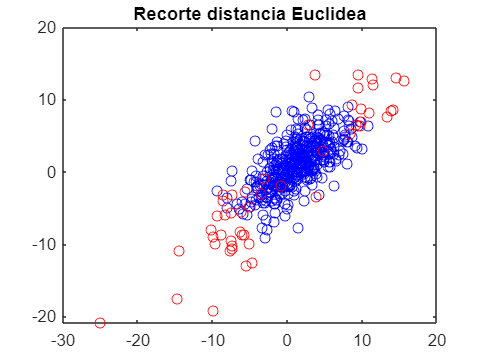

% d2 = sqrt(sum((data-mean(data)).^2,2))
pc_euclidea = prctile(d_Euclidea,90);
I_euclidea = find(d_Euclidea>pc_euclidea);
plot(data(:,1),data(:,2), 'ob')
hold on;
plot(data(I_euclidea,1),data(I_euclidea,2),'or')
title('Recorte distancia Euclidea')
hold off;

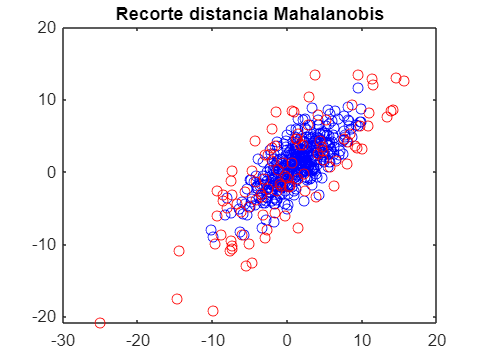


% Distancia de Mahalanobis
D = mahal(data,data);
plot(data(:,1),data(:,2), 'ob')
hold on;
pc = prctile(D,80);
I = find(D>pc);
plot(data(I,1),data(I,2),'or')
title('Recorte distancia Mahalanobis')
hold off;

datafiltrado = data;
datafiltrado(I,:) = [];

%Indicador R datos recortados
C = cov(datafiltrado);
CI = inv(C);
d1 = diag(C);
d2 = diag(CI);
Rfiltrado = 1 - 1./(d1.*d2)

Rfiltrado =     0.7750
    0.7117
    0.6772
    0.6012
    0.8055


## Punto 2.b Correlacion de Kendall

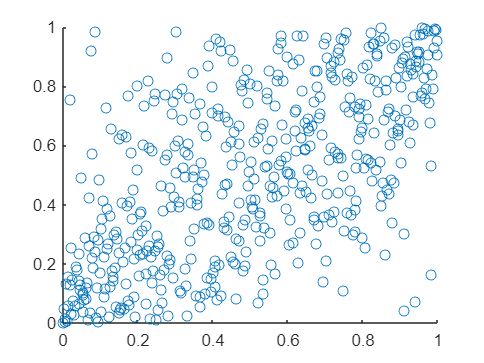

kendall = corr(data, 'type', 'Kendall');

minimo = min(kendall,[],"all");
[a, b] = find(kendall == minimo,1);

x = data(:,a);
y = data(:,b);
scatter(empiric(x),empiric(y))

## Punto 2.c Proyeccion maxima y minima variabilidad

data_min = [x,y]

data_min =    -5.5800    1.8600
   -3.8900    2.5600
   -7.7500   -5.7300
   -1.3300   -9.1700
    7.9500    6.5200
    3.9300    5.7700
   -0.7500   -3.8800
    1.4500   -5.0900
   -1.8100   -6.8800
   -2.5700   -1.8100


C = cov(data_min);
[vector, valor] = eig(C)

vector =     0.6796   -0.7336
   -0.7336   -0.6796


valor =     7.4669         0
         0   33.3259


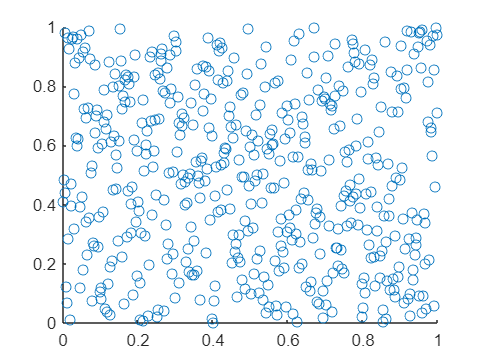

proyeccion_max = data_min*vector(:,end);
proyeccion_min = data_min*vector(:,1);
scatter(empiric(proyeccion_max),empiric(proyeccion_min))

var(proyeccion_max)

ans = 33.3259

## Punto 2.d

media = mean(data)

media =     1.1123    0.9879    1.0668    1.1077    0.9717


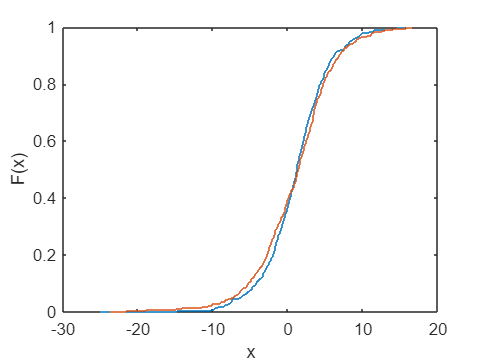

[value_max, maximo] = max(media);
[value_min, minimo] = min(media);
ecdf(data(:,maximo))
hold on
ecdf(data(:,minimo))
hold off

function [emp] = empiric(col)
    n = length(col);
    emp = [];
    for i = 1:length(col)
        ratio = (length(col(col<=col(i))))/n;
        emp = [emp, ratio];
    end

end